**Demonstrator Notebook for plottingObj**

**Contains demos for how to make different kinds of  basic plots using plottingObj**

**CTRL+ENTER to execute a cell**

**CTRL+SHIFT+ENTER to execute a cell and advance**

**CTRL+ALT+ENTER to create a new cell at the cursor**

clearvars
close all
clc

The cell below creates the trajectories and bodies used in this demo, and must be run. All other cells are only dependent on this cell

% Trajectory Setup
t=0:0.1:10; %independent variable
x=(t.^2)/max(t); %x selected to show an acceleration a_x when animated
y=5*sin(t); %y selected to show an oscillation in y
theta=atan2(diff(y),diff(x)); %heading aligned with \vec{v}
theta=[theta theta(:,end)];

traj_xy=[x;y]; % 2xT trajectory
traj_xyt=[x;y;theta]; % 3xT trajectory

%Body Setup
% for some demos, we'll use a simple triangle body
tx=[-0.5,-0.5,0.5,-0.5];
ty=[0.25,-0.25,0,0.25];%need four points to close the loop; return to the starting point [a->b->c->a]
triangle_body=[tx;ty];

%For contour demos, we'll use a simple contour: F(x,y)=distance from origin
[cX,cY]=meshgrid(-10:0.5:10,-10:0.5:10);
cF=sqrt(cX.^2+cY.^2);

contour_body=0.25*[cX(:),cY(:),cF(:)]';

%We also need dynamic versions of the bodies; those changing in time
dyn_triangle_body=zeros([size(triangle_body) length(t)]);
dyn_contour_body=zeros([size(contour_body) length(t)]);


dynamic_scaler=sin(t);
for k=1:length(t)
    dyn_triangle_body(:,:,k)=dynamic_scaler(k)*triangle_body;
    dyn_contour_body(:,:,k)=dynamic_scaler(k)*contour_body;
end

**I: Trajectory Only**

There are 3 options for how to plot the trajectory, as set by the 'traj_mode' keyword argument

- 'plot' -plot the entire trajectory at once

- 'drag' -plot increasing segments of the trajectory as an internal iterator increments. Each time obj.get_plots() is called, the iterator advances, so calling obj.get_plots in a loop will plot the animation

- 'dot' -plot just the point on the trajectory corresponding to the iterator value

Note that traj can have two rows (x,y), or three rows (x,y,theta), but this distinction only matters when plotting bodies; the examples below use traj_xy, but commented versions using traj_xyt are provided for testing

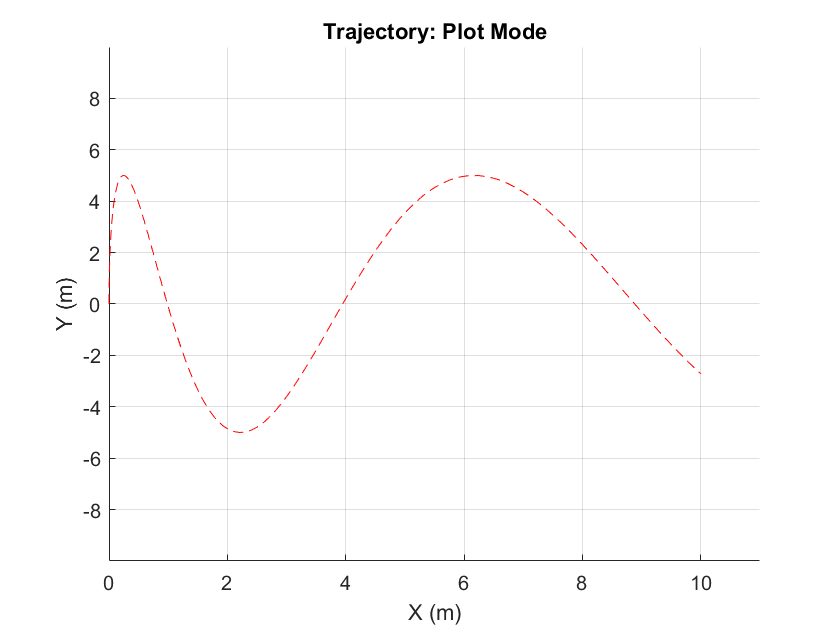

%%%% 'plot' mode
    fig=figure()
    traj_args={'r--'}; %takes typical plot args
    curve=plottingObj('traj',traj_xy,'traj_mode','plot','traj_args',traj_args);
    curve.get_plots();
    grid on
    xlim(1.1*[min(x),max(x)]);
    ylim(2*[min(y),max(y)]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Trajectory: Plot Mode')

    
%     fig=figure()
%     traj_args={'r--'}; %takes typical plot args
%     curve=plottingObj('traj',traj_xyt,'traj_mode','plot','traj_args',traj_args);
%     curve.get_plots();
%     grid on
%     xlim(1.1*[min(x),max(x)]);
%     ylim(2*[min(y),max(y)]);
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     title('Trajectory: Plot Mode')
    

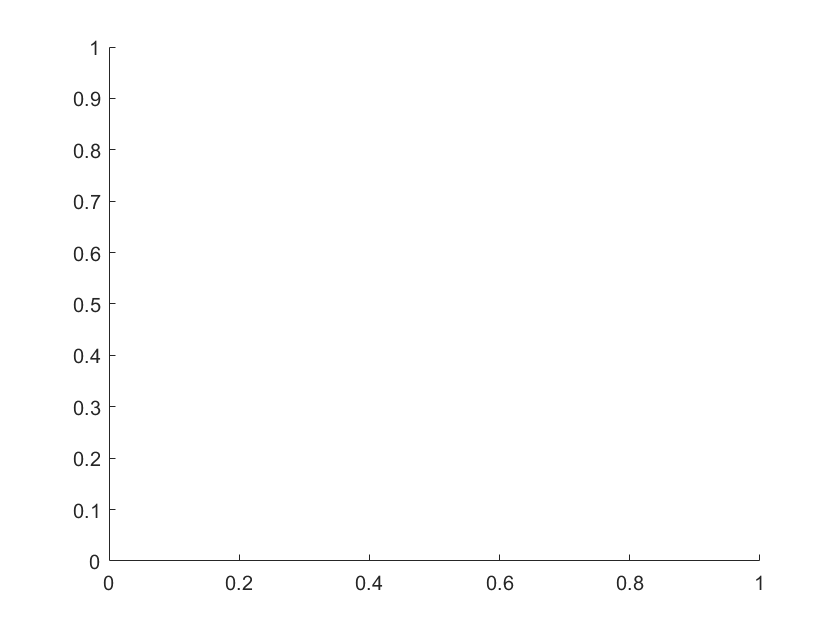

%%%% 'drag' mode
    fig=figure()
    traj_args={'m-'};  %takes typical plot args
    curve=plottingObj('traj',traj_xy,'traj_mode','drag','traj_args',traj_args);
    for i=1:length(t)
        plts=curve.get_plots();
        xlim(1.1*[min(x),max(x)]);
        ylim(2*[min(y),max(y)]);
        xlabel('X (m)')
        ylabel('Y (m)')
        title('Trajectory: Drag Mode')
        pause(0.1);
        cla('reset')
    end

    
%     fig=figure()
%     traj_args={'m-'};  %takes typical plot args
%     curve=plottingObj('traj',traj_xyt,'traj_mode','drag','traj_args',traj_args);
%     for i=1:length(t)
%         plts=curve.get_plots();
%         xlim(1.1*[min(x),max(x)]);
%         ylim(2*[min(y),max(y)]);
%         xlabel('X (m)')
%         ylabel('Y (m)')
%         title('Trajectory: Drag Mode')
%         pause(0.1);
%         cla('reset')
%     end

 %%%% 'dot' mode
    fig=figure()
    traj_args={'g*'}; %Takes typical plot args, but it's recommended to have a marker like '*', pure lines will not display
    curve=plottingObj('traj',traj_xy,'traj_mode','dot','traj_args',traj_args);
    for i=1:length(t)
        plts=curve.get_plots();
        xlim(1.1*[min(x),max(x)]);
        ylim(2*[min(y),max(y)]);
        xlabel('X (m)')
        ylabel('Y (m)')
        title('Trajectory: Dot Mode')
        pause(0.1);
        cla('reset');
    end

    
%     fig=figure()
%     traj_args={'g*'}; %Takes typical plot args, but it's recommended to have a marker like '*', pure lines will not display
%     curve=plottingObj('traj',traj_xyt,'traj_mode','dot','traj_args',traj_args);
%     for i=1:length(t)
%         plts=curve.get_plots();
%         xlim(1.1*[min(x),max(x)]);
%         ylim(2*[min(y),max(y)]);
%         xlabel('X (m)')
%         ylabel('Y (m)')
%         title('Trajectory: Dot Mode')
%         pause(0.1);
%         cla('reset');
%     end

**II: Body Only**

There are 3 options for how to plot the body, as set by the 'body_mode' keyword argument. 

- 'plot' -plot the outline traced by the points in body. Default behavior if body has 2 rows

- 'fill' -fill the outline traced by the points in the body

- 'contour' -plot a contour plot of the field defined by body. Default behavior when body has 3 rows. Note that plottingObj will 'unpack' the body to a meshgrid; it will assume a square shape, but different grids can be provided with the 'body_mtrx_shape' keyword argument

bodies can be static or dynamic: 

where pti=[xi yi]'

static bodies have a single form: stat_bod= [pt1 pt2 ... ptn] (A 2D matrix of xy points)

dynamic bodies change shape over time body= [stat_bod(1) , stat_bod(2) ,..., stat_bod(N) ] (A 3D matrix, a bunch of bodies layered together)

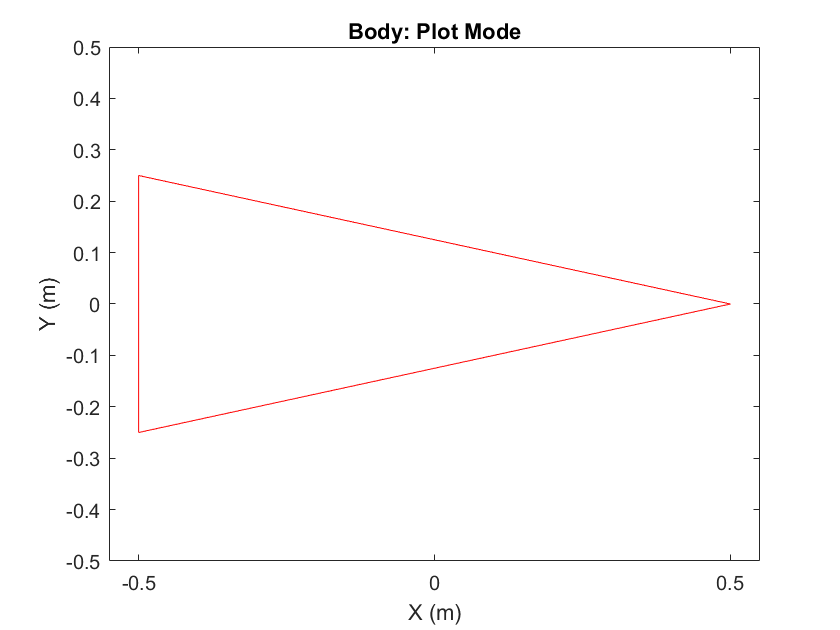

%%% Static Body
    fig=figure()
    body_args={'r-'}; %takes typical plot args
    curve=plottingObj('body',triangle_body,'body_args',body_args); %Mode not provided since 'plot' will be default
    curve.get_plots();
    xlim(1.1*[min(triangle_body(1,:)),max(triangle_body(1,:))]);
    ylim(2*[min(triangle_body(2,:)),max(triangle_body(2,:))]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Body: Plot Mode')

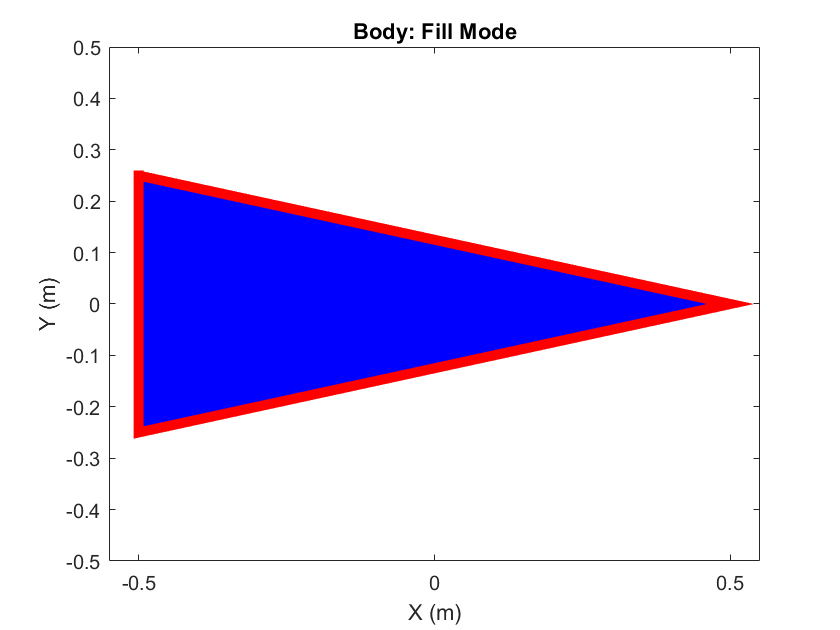

%%% Static Fill
    fig=figure()
    body_args={'blue','EdgeColor','red','LineWidth',5}; %takes fill() args. A color MUST be provided first
    curve=plottingObj('body',triangle_body,'body_mode','fill','body_args',body_args); %Mode provided since 'fill' is not default
    curve.get_plots();
    xlim(1.1*[min(triangle_body(1,:)),max(triangle_body(1,:))]);
    ylim(2*[min(triangle_body(2,:)),max(triangle_body(2,:))]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Body: Fill Mode')

%%% Static Contour
    fig=figure()
    body_args={20}; %For contour, use contour() arg patterns that use X,Y,Z, inputs.
    curve=plottingObj('body',contour_body,'body_args',body_args); %Mode not provided since contour is default behavior for this size body
    curve.get_plots()

ans = 1×2 cell array
    {0×0 double}    {1×1 Contour}


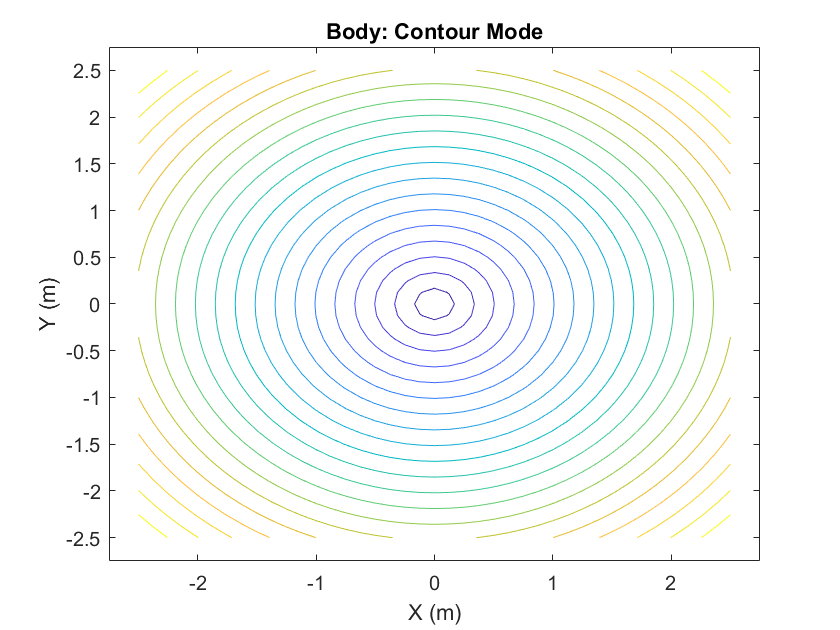

    xlim(1.1*[min(contour_body(1,:,:)),max(contour_body(1,:,:))]);
    ylim(1.1*[min(contour_body(2,:,:)),max(contour_body(2,:,:))]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Body: Contour Mode')

%%% Dynamic Body
    fig=figure()
    body_args={'k-'}; %takes typical plot args
    curve=plottingObj('body',dyn_triangle_body,'body_args',body_args); %Mode not provided since 'plot' will be default
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(dyn_triangle_body(1,:,:),[],'all'),max(dyn_triangle_body(1,:,:),[],'all')]);
    ylim(2*[min(dyn_triangle_body(2,:,:),[],'all'),max(dyn_triangle_body(2,:,:),[],'all')]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Dynamic Body: Plot Mode')
    
    pause(0.1)
    cla('reset')
    end


%%% Dynamic Fill
    fig=figure()
    body_args={'blue','EdgeColor','r'}; %takes fill() args
    curve=plottingObj('body',dyn_triangle_body,'body_mode','fill','body_args',body_args);
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(dyn_triangle_body(1,:,:),[],'all'),max(dyn_triangle_body(1,:,:),[],'all')]);
    ylim(2*[min(dyn_triangle_body(2,:,:),[],'all'),max(dyn_triangle_body(2,:,:),[],'all')]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Dynamic Body: Fill Mode')
    
    pause(0.1)
    cla('reset')
    end   
    

%%% Dynamic Contour
    fig=figure()
    body_args={20}; %For contour, use contour() arg patterns that use X,Y,Z, inputs.
    curve=plottingObj('body',dyn_contour_body,'body_args',body_args);
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(dyn_contour_body(1,:,:),[],'all'),max(dyn_contour_body(1,:,:),[],'all')]);
    ylim(1.1*[min(dyn_contour_body(2,:,:),[],'all'),max(dyn_contour_body(2,:,:),[],'all')]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Dynamic Body: Contour Mode')
    
    pause(0.1)
    cla('reset')
    end   

**II: Body & Trajectory**

Any combination of the previous example can be used to send a body along a trajectory. The body can be static or dynamic. 

If body is dynamic, and/or body or traj is longer  than the other, then a few options are possible. 

    If the body is shorter and 'cycle_body' keyword argument is false (default), then the body will simply hold its final form obj.body(:,:,end). Otherwise, it will reset to its initial configuration and start again.

    If the traj is shorter and 'cycle_traj' keyword argument is false (default), then the body will simply hold its final form-> obj.traj(:,end). Otherwise, it will reset to its initial configuration and start again.

To not plot the trajectory, pass in 'traj_mode','blank' or use dot mode with out markers

A few examples are given here of the various combinations; but others are all possible

- A dynamic body plot translating along a trajectory without heading (plot traj)

- A static body fill translating along a trajectory with heading (blank traj)

- A dynamic contour translating along a trajectory with heading (drag traj)

%%% Dynamic Body Along Trajectory Without Heading
    fig=figure()

fig =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


    traj_args={'r-.'}

traj_args = 1×1 cell array
    {'r-.'}


    body_args={'k-'}; %For contour, use contour() arg patterns that use X,Y,Z, inputs.
    curve=plottingObj('traj',traj_xy,'traj_mode','blank','traj_args',traj_args,'body',dyn_triangle_body,'body_mode','plot','body_args',body_args);
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(x),max(x)]);
    ylim(2*[min(y),max(y)]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Dynamic Body along Trajectory')
    grid on
    pause(0.1)
    cla('reset')
    end 

%%% Static Fill Along Trajectory With Heading
    fig=figure()
    traj_args={'r-.'}

traj_args = 1×1 cell array
    {'r-.'}


    body_args={'blue'}; %For contour, use contour() arg patterns that use X,Y,Z, inputs.
    curve=plottingObj('traj',traj_xyt,'traj_mode','blank','traj_args',traj_args,'body',triangle_body,'body_mode','fill','body_args',body_args);
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(x),max(x)]);
    ylim(2*[min(y),max(y)]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Static Fill Along Trajectory')
    
    grid on
    pause(0.1)
    cla('reset')
    end 

%%% Dynamic Contour Along Trajectory With Heading
    fig=figure()
    traj_args={'r-'}
    body_args={20}; %For contour, use contour() arg patterns that use X,Y,Z, inputs.
    curve=plottingObj('traj',traj_xyt,'traj_mode','drag','traj_args',traj_args,'body',dyn_contour_body,'body_args',body_args);
    for i=1:length(t)
    plts=curve.get_plots();
    xlim(1.1*[min(x),max(x)]);
    ylim(2*[min(y),max(y)]);
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Dynamic Contour Along Trajectory')
    
    pause(0.1)
    cla('reset')
    end 
    